**Лабораторорная работа №2**

Параметрический синтез и исследование цифровой системы управления

 с П-регулятором и объектом в виде последовательно включенных 

апериодического и интегрирующего звеньев 

из условия обеспечения заданного переходного процесса.

Выполнил студент группы R34352

Эргле Екатерина Артуровна

Преподаватель 

Ловлин Сергей Юрьевич

Санкт-Петербург 2023

%вариант
ob.R = 0.1+unifrnd(-0.03,0.03);
ob.L = 0.02+unifrnd(-0.01,0.01);
ob.J = 100+unifrnd(-10,10);
ob.Ce = 2;
ob.Cm = Ce;
save ('data.mat','ob')

## **Задание 1. Моделирование П-регулятора.**

Снять временные диаграммы, иллюстрирующие работу эквивалентных аналогового и цифрового П-регуляторов при линейно нарастающем входном воздействии на входе регулятора для случая вычислительной задержки ε = 0. Представить схему модели.

load ('data.mat')
an.Kp=10;
dsc.Kp=10;

Tmdl=1;
To=0.05;

warning off
SimNew = sim('lab2_1.slx','ReturnWorkspaceOutputs', 'on') ;
warning on


t=SimNew.tout(:,1);
an.y=SimNew.ScopeData(:,2);
dsc.y=SimNew.ScopeData(:,3);

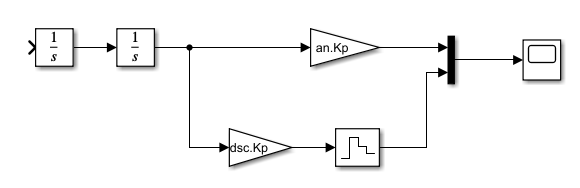

*Рисунок 1 – Схема моделирования **Simulink*

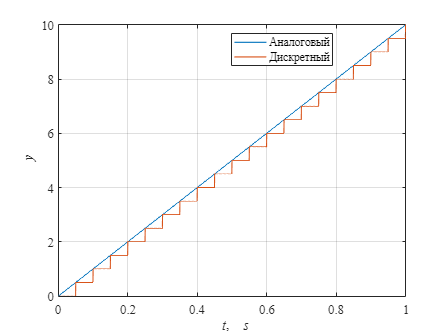

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'LineWidth',1)
hold on
grid on
plot(t,dsc.y,'LineWidth',1)
xlabel('\it t\rm, \it s')
ylabel('\it y')
hold off
legend('Аналоговый', 'Дискретный')

legend("Position",[0.51667,0.80437,0.22679,0.096429])

*Рисунок 2 – Временные диаграммы*

## **Задание 2. Синтез системы с использованием «метода переоборудования»**

### **Синтез внутреннего тока контура**

syms ia ua w e M
syms R L J Ce
syms dia dw

eq(1)=L*dia+R*ia==ua-e;
eq(2)=J*dw==M; %1 закон ньютона
eq(3)=e==Ce*w;
eq(4)= M==Ce*ia;

S1=solve(eq,[dia dw e M]);
%disp(collect(S1.dia, [ia w ua]));%производная по току
%disp(collect(S1.dw, [ia w ua]));%производная по частоте вращения

A=[-R/L -Ce/L;
    Ce/J 0];
B=[1/L; 0];
C=[1 0];
D=0;

syms s
Wia = C*(s*eye(2) - A)^-1*B + D ;

Передаточная функция системы

disp(collect(Wia, s)) 

$$\frac{J\,s}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

Упрощенная передаточная функция

Wia_smpl = 1/(L*s+R); % Пренебрегаем Се, т.к. оно мало -> упрощенная передаточная функция
disp(collect(Wia_smpl, s))

$$\frac{1}{L\,s+R}$$

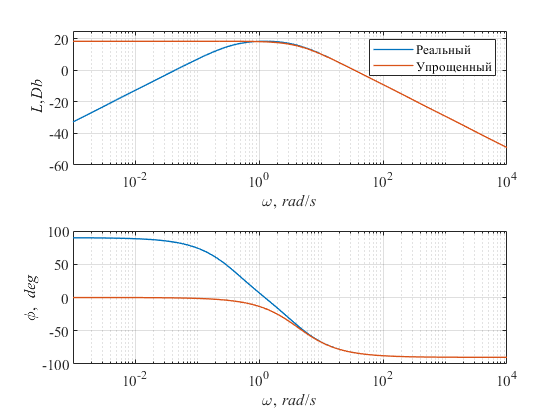


wfr= 10.^(-3:0.01:4);
sfr = 1i*wfr;
Wia_tf =  ob.J*sfr./(ob.J*ob.L*sfr.^2+ob.J*ob.R*sfr+ob.Ce^2);
Wia_sm =  1./(ob.L*sfr+ob.R);

Lw_tf= 20*log10(abs(Wia_tf));
phi_tf = angle(Wia_tf)*180/pi;

Lw_sm= 20*log10(abs(Wia_sm));
phi_sm = angle(Wia_sm)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

ax(1) = subplot(2,1,1);
plot(wfr,Lw_tf,'LineWidth', 1)
hold on
grid on
plot(wfr,Lw_sm,'LineWidth', 1)
set(ax(1), 'XScale' , 'log')
xlabel('\omega\rm,\it rad\rm/\its')
ylabel('\it L\rm,\itDb')

ax(2) = subplot(2,1,2);
plot(wfr,phi_tf,'LineWidth', 1)
hold on
grid on
plot(wfr,phi_sm,'LineWidth', 1)
set(ax(2), 'XScale' , 'log')
xlabel('\omega\rm,\it rad\rm/\its')
ylabel('\phi, \it deg')

linkaxes(ax,'x')

subplot(2,1,1)
xlim([0 10000])
ylim([-60 25])
legend('Реальный', 'Упрощенный')

*Рисунок 3 – *Сравнение реальной и упрощенной AЧХ и ФЧХ

**Расчет ПИ регулятора тока**

syms Tt s
%настройка линечного оптимума
Wol = 1/(Tt*s)

$$Wol = \frac{1}{\mathrm{Tt}\,s}$$

Передаточная фунция резулятора

Wreg = Wol/Wia_smpl;
disp(collect(Wreg, s))

$$\frac{L\,s+R}{\mathrm{Tt}\,s}$$

Анализ области применения упрощенной передаточной функции при синтезе контура тока

ob.J*ob.R/ob.Ce^2

ans = 2.7504

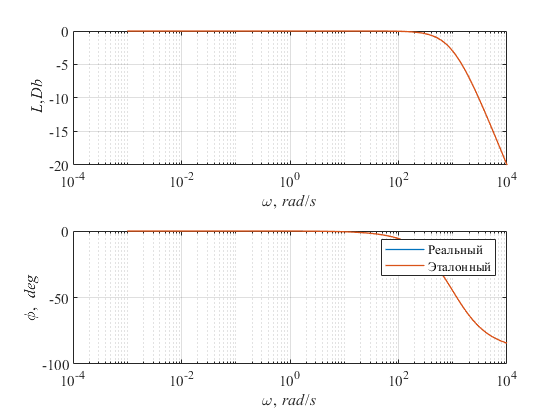

Tt=0.001;

wfr= 10.^(-3:0.01:4);
sfr = 1i*wfr;
Wia_tf =  ob.J*sfr./(ob.J*ob.L*sfr.^2+ob.J*ob.R*sfr+ob.Ce^2);
Wia_sm =  1./(ob.L*sfr+ob.R);
Wreg_tf = (ob.L*sfr+ob.R)./(Tt*sfr);

Wreal = Wreg_tf.*Wia_tf./(1+Wreg_tf.*Wia_tf);
Wet = Wreg_tf.*Wia_sm./(1+Wreg_tf.*Wia_sm);

Lw_tf= 20*log10(abs(Wreal));
phi_tf = angle(Wreal)*180/pi;
Lw_sm= 20*log10(abs(Wet));
phi_sm = angle(Wet)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

ax(1) = subplot(2,1,1);
plot(wfr,Lw_tf,'LineWidth', 1)
hold on
grid on
plot(wfr,Lw_sm,'LineWidth', 1)
set(ax(1), 'XScale' , 'log')
xlabel('\omega\rm,\it rad\rm/\its')
ylabel('\it L\rm,\itDb')

ax(2) = subplot(2,1,2);
plot(wfr,phi_tf,'LineWidth', 1)
hold on
grid on
plot(wfr,phi_sm,'LineWidth', 1)
set(ax(2), 'XScale' , 'log')
xlabel('\omega\rm,\it rad\rm/\its')
ylabel('\phi, \it deg')

linkaxes(ax,'x')
legend('Реальный', 'Эталонный')

*Рисунок 4 – *Сравнение реальной и эталонной AЧХ и ФЧХ при Т=0,001

### Моделирование работы контура тока

Tt=0.001;
crl.Kpa = ob.L/Tt; 
crl.Kia = ob.R/Tt;
Tmdl = 0.01;
warning off
b = sim('SUAP_2_lb2','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
SUAP_2_lb2/Current Reg/Gain
SUAP_2_lb2/Current Reg/Sum
SUAP_2_lb2/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_2_lb2/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_2_lb2/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_2_lb2/Current Reg/Sum1 (algebraic variable)


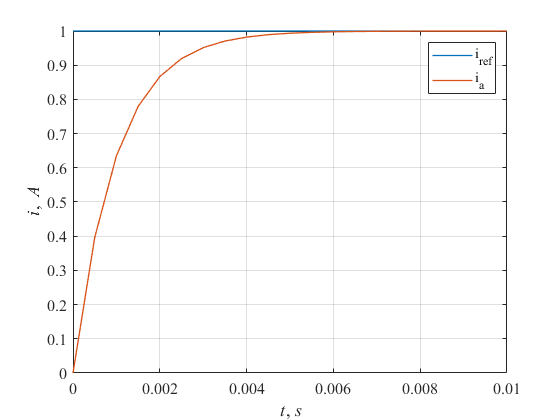

warning on

t = b.ia(:,1);
iref = b.ia(:,2);
isens = b.ia(:,3);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,iref,'LineWidth', 1)
hold on
grid on
plot(t,isens,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm, \it A')
legend ('i_{ref}', 'i_a')

*Рисунок 4 – Моделирование работы контура тока*

### Расчет цифрового П-регулятор скорости

syms Tu Tt s 
syms kdw %коэф. предачи датчика скорости
Wcrl = 1/(Tt*s+1);
Wob2=Ce*kdw/(J*s);

Передаточная функция разомкнутой системы, настроенной на технический оптимум

Tu=Tt;
Wol = 1/(2*Tu*s*(Tu*s+1));
Wreg = Wol/(Wcrl*Wob2);
disp(collect(Wreg,s)) 

$$\frac{J}{2\,\mathrm{Ce}\,\mathrm{Tt}\,\mathrm{kdw}}$$

### Моделирование работы системы, настроенной на технический оптимум

Tt=0.001;
To=0.001;
crl.Kpa = ob.L/Tt; 
crl.Kia = ob.R/Tt;
spl.Tu=Tt;
kdw = 180/pi;
Tmdl = 0.03;

#### To=0.1*Tu

spl.Kpa = ob.J/kdw/2/ob.Ce/Tt;
spl.Kpd = spl.Kpa;
To=0.1*spl.Tu

To = 1.0000e-04


warning off
b = sim('SUAP_2b_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_2b_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_2b_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_2b_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_2b_lb2/Ob/Current Reg/Sum1
SUAP_2b_lb2/Ob/Current Reg/Gain
SUAP_2b_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebra

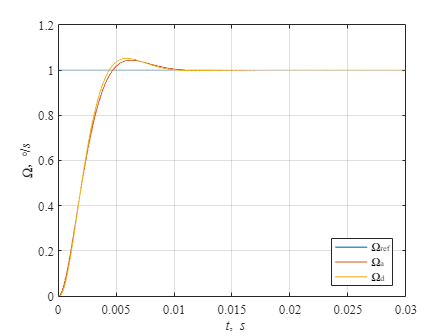

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d', 'location', 'best')


%заданная скорость, скорость с аналоговым п-регулятором, с дискретным
%п-регулятором

*Рисунок 5 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором*

t = b.w(:,1);
w_ref = b.w(:,2);
wd_sens = b.w(:,4);

Время переходного процесса(попадание в 5% зону)

t0=t(1);
y=wd_sens;
y0=wd_sens(1);
yss= wd_sens(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 3.9*Tu

t0=t(1);
y=wd_sens;
y0=wd_sens(1);
yss= wd_sens(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 6.3*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 5.2%


#### To=1*Tu

spl.Kpa = ob.J/kdw/2/ob.Ce/Tt;
spl.Kpd = spl.Kpa;
To=1*spl.Tu;

warning off
b = sim('SUAP_2b_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_2b_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_2b_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_2b_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_2b_lb2/Ob/Current Reg/Sum1
SUAP_2b_lb2/Ob/Current Reg/Gain
SUAP_2b_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebra

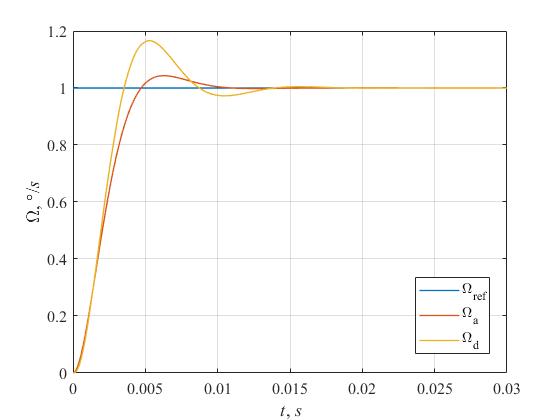

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d', 'location', 'best')

*Рисунок 6 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором*

t = b.w(:,1);
w_ref = b.w(:,2);
wd_sens = b.w(:,4);

Время переходного процесса(попадание в 5% зону)

t0=t(1);
y=wd_sens;
y0=wd_sens(1);
yss= wd_sens(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 3.3*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 7.7*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 16.6%


Параметры переходных процессов

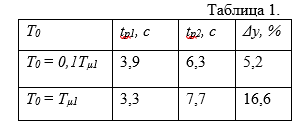

## **Задание 3. Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового П-регулятора для случая вычислительной задержки ε = 0.**

To=spl.Tu

To = 1.0000e-03

for i=1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('SUAP_3_lb2','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 

Found algebraic loop containing: 
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_3_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_3_lb2/Ob/Current Reg/Sum1
SUAP_3_lb2/Ob/Current Reg/Gain
SUAP_3_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

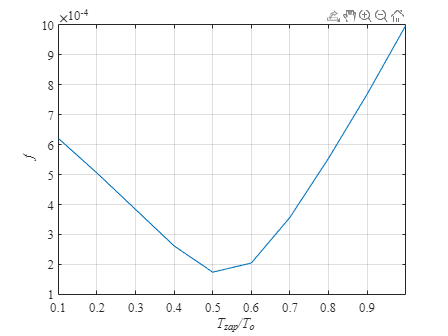

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')

xlim([0.1 1])

*Рисунок 7 – График функционала системы*

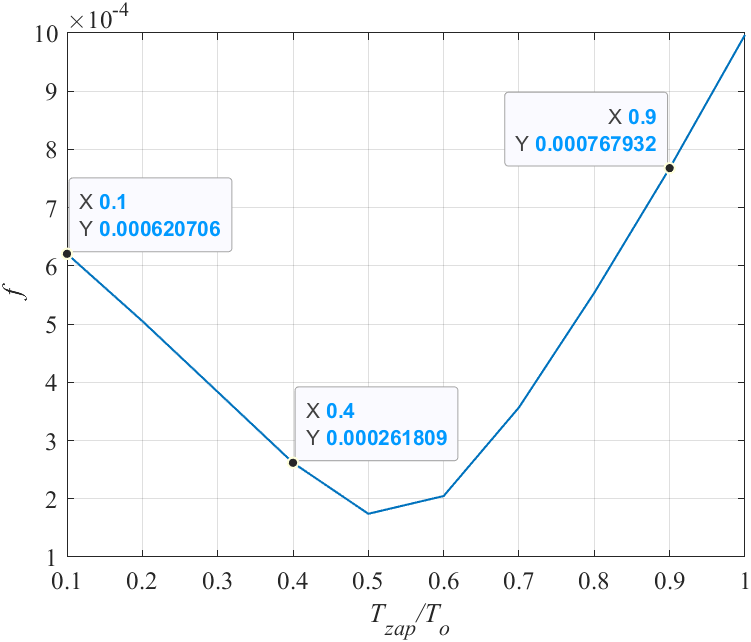

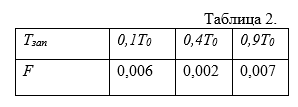

### Перенастройка с помощью метода переоборудования

#### To =Tt

To=1*Tt;
spl.Tz=To*0.5; % вот сюда минимум 0.5
spl.Tu=Tt+spl.Tz;
spl.Kpa = ob.J/kdw/2/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;


warning off
b = sim('SUAP_3_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_3_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_3_lb2/Ob/Current Reg/Sum1
SUAP_3_lb2/Ob/Current Reg/Gain
SUAP_3_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

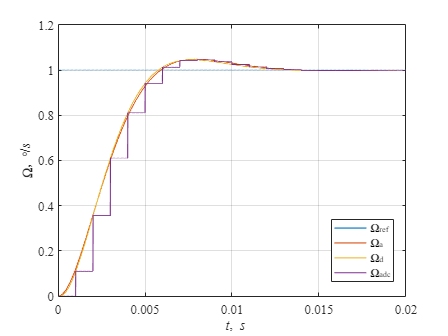

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);
wadc = b.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
plot(t,wadc,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d','\Omega_{adc}', 'location', 'best')
xlim([0 0.02])

*Рисунок 7 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором, цифровой системы *

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

Время переходного процесса

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/Tt)

Время переходного процесса t1: 5.1*Tu


D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 3.4*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 4.5%


#### To =2Tt

To=2*Tt;
spl.Tz=To*0.5; %И сюда минмиум
spl.Tu=Tt+spl.Tz; 
spl.Kpa = ob.J/kdw/2/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;


warning off
b = sim('SUAP_3_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_3_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_3_lb2/Ob/Current Reg/Sum1
SUAP_3_lb2/Ob/Current Reg/Gain
SUAP_3_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

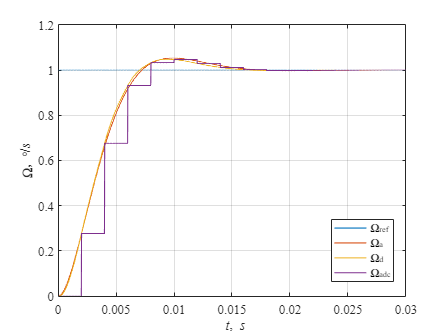

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);
wadc = b.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
plot(t,wadc,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d','\Omega_{adc}', 'location', 'best')

*Рисунок 8 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором, цифровой системы *

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

Время переходного процесса

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 3.1*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 3.1*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 4.7%


Параметры переходных процессов

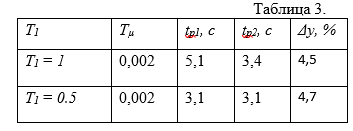

## Задание 4. **Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового П-регулятора для случая вычислительной задержки ε = *****Т******0*****.**

Tt=0.001;
To=Tt;
spl.Tu=Tt;
spl.Kpa = ob.J/kdw/3/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;
Tmdl = 0.15;

for i=1:20
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('SUAP_4_lb2','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 

Found algebraic loop containing: 
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_4_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_4_lb2/Ob/Current Reg/Sum1
SUAP_4_lb2/Ob/Current Reg/Gain
SUAP_4_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

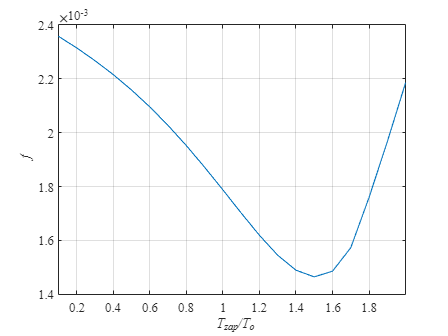

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0.1 2])

*Рисунок 7 – График функционала системы*

### Перенастройка с помощью метода переоборудования

#### To =Tt

To=1*Tt;
spl.Tz=1.5*To; %!!1 Вот сюда минимум подставляем 1,5
spl.Tu=Tt+spl.Tz;
spl.Kpa = ob.J/kdw/3/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;
Tmdl = 0.03;

warning off
b = sim('SUAP_4_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_4_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_4_lb2/Ob/Current Reg/Sum1
SUAP_4_lb2/Ob/Current Reg/Gain
SUAP_4_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

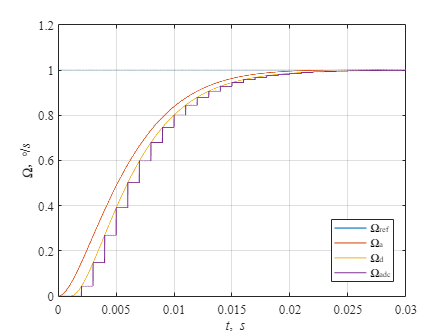

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);
wadc = b.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
plot(t,wadc,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d','\Omega_{adc}', 'location', 'best')

*Рисунок 10 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором, цифровой системы *

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 6.1*Tu


D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 6.1*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 0.0%


#### To =2Tt

Tt=0.001;
To=2*Tt;
spl.Tz=1.5*To;
spl.Tu=Tt+spl.Tz;
spl.Kpa = ob.J/kdw/3/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;

Tmdl=0.05;
warning off
b = sim('SUAP_4_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_4_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_4_lb2/Ob/Current Reg/Sum1
SUAP_4_lb2/Ob/Current Reg/Gain
SUAP_4_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

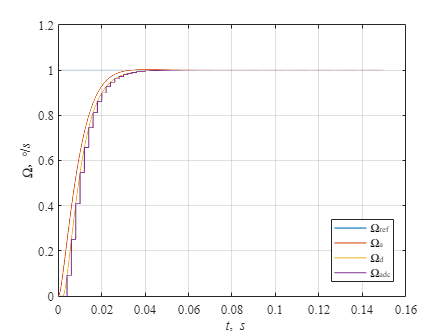

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);
wadc = b.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
plot(t,wadc,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d','\Omega_{adc}', 'location', 'best')

*Рисунок 11 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором, цифровой системы *

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 6.1*Tu


D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 6.1*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 0.0%


Параметры переходных процессов

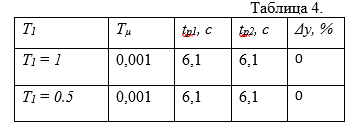

## Задание 5. **Осуществить синтез системы из условия обеспечения в ней «биномиальной настройки» и провести моделирование.**

### Моделирование работы системы настроенной на биномиальный оптимум.

Tt=0.001;
To=0.001;
crl.Kpa = ob.L/Tt; 
crl.Kia = ob.R/Tt;
spl.Tu=Tt;
kdw = 180/pi;
Tmdl = 0.03;

#### To=0.1*Tu

spl.Kpa = ob.J/kdw/3/ob.Ce/Tt;
spl.Kpd = spl.Kpa;
To=0.1*spl.Tu;

warning off
b = sim('SUAP_2b_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_2b_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_2b_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_2b_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_2b_lb2/Ob/Current Reg/Sum1
SUAP_2b_lb2/Ob/Current Reg/Gain
SUAP_2b_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebra

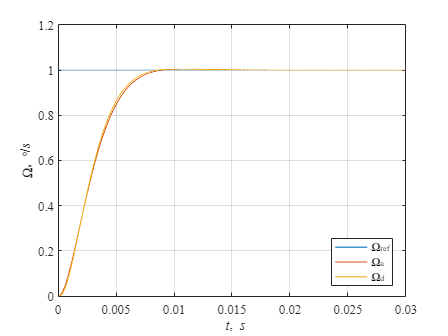

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d', 'location', 'best')

*Рисунок 12 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором*

t = b.w(:,1);
w_ref = b.w(:,2);
wd_sens = b.w(:,4);
t0=t(1);
y=wd_sens;
y0=wd_sens(1);
yss= wd_sens(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 6.3*Tu

t0=t(1);
y=wd_sens;
y0=wd_sens(1);
yss= wd_sens(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 6.3*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 0.4%


#### To=1*Tu

spl.Kpa = ob.J/kdw/3/ob.Ce/Tt;
spl.Kpd = spl.Kpa;
To=1*spl.Tu;

warning off
b = sim('SUAP_2b_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_2b_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_2b_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_2b_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_2b_lb2/Ob/Current Reg/Sum1
SUAP_2b_lb2/Ob/Current Reg/Gain
SUAP_2b_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebra

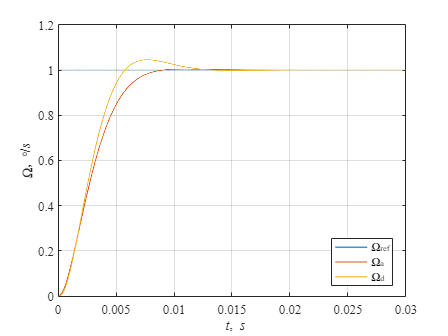

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d', 'location', 'best')

*Рисунок 13 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором*

t = b.w(:,1);
w_ref = b.w(:,2);
wd_sens = b.w(:,4);
t0=t(1);
y=wd_sens;
y0=wd_sens(1);
yss= wd_sens(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 5.1*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 5.1*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.0454

fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 4.5%


### **Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового П-регулятора для случая вычислительной задержки ε = 0.**

To=spl.Tu

To = 1.0000e-03

for i=1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('SUAP_3_lb2','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 

Found algebraic loop containing: 
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_3_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_3_lb2/Ob/Current Reg/Sum1
SUAP_3_lb2/Ob/Current Reg/Gain
SUAP_3_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

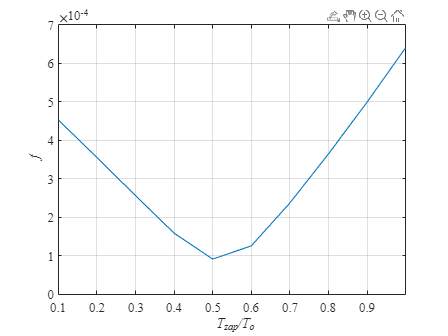

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0.1 1])

*Рисунок 14 – График функционала системы*

#### Перенастройка с помощью метода переоборудования

#### To =Tt

To=1*Tt;
spl.Tz=To*0.5; %сюда этот мин
spl.Tu=Tt+spl.Tz;
spl.Kpeyrb = ob.J/kdw/3/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;


warning off
b = sim('SUAP_3_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_3_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_3_lb2/Ob/Current Reg/Sum1
SUAP_3_lb2/Ob/Current Reg/Gain
SUAP_3_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

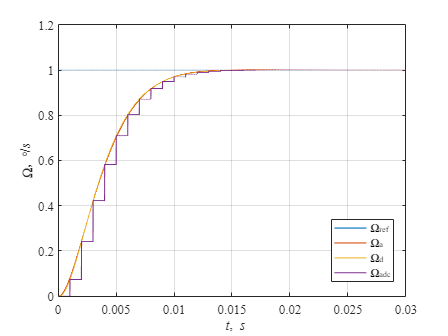

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);
wadc = b.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
plot(t,wadc,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d','\Omega_{adc}', 'location', 'best')

*Рисунок 15 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором, цифровой системы *

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 6.0*Tu


D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 6.0*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 0.0%


#### To =2Tt

To=2*Tt;
spl.Tz=To*0.5;
spl.Tu=Tt+spl.Tz;
spl.Kpa = ob.J/kdw/3/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;


warning off
b = sim('SUAP_3_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_3_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_3_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_3_lb2/Ob/Current Reg/Sum1
SUAP_3_lb2/Ob/Current Reg/Gain
SUAP_3_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

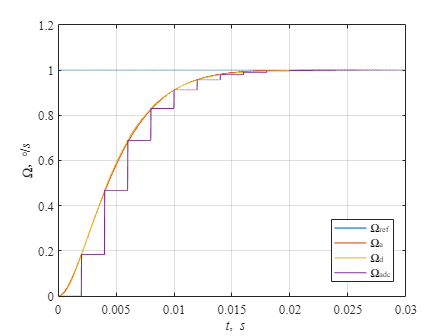

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);
wadc = b.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
plot(t,wadc,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d','\Omega_{adc}', 'location', 'best')

*Рисунок 16 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором, цифровой системы *

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 5.8*Tu


D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 5.8*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 0.0%


### **Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового П-регулятора для случая вычислительной задержки ε = *****Т******0*****.**

Tt=0.001;
To=Tt;
spl.Tu=Tt;
spl.Kpa = ob.J/kdw/3/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;
Tmdl = 0.15;

for i=1:20
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('SUAP_4_lb2','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 

Found algebraic loop containing: 
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_4_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_4_lb2/Ob/Current Reg/Sum1
SUAP_4_lb2/Ob/Current Reg/Gain
SUAP_4_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

Program interruption (Ctrl-C) has been detected.

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0.1 2])

*Рисунок 17 – График функционала системы*

#### Перенастройка с помощью метода переоборудования

#### To =Tt

To=1*Tt;
spl.Tz=1.5*To; %!!1 Вот сюда минимум подставляем 1,5
spl.Tu=Tt+spl.Tz;
spl.Kpa = ob.J/kdw/3/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;
Tmdl = 0.03;

warning off
b = sim('SUAP_4_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_4_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_4_lb2/Ob/Current Reg/Sum1
SUAP_4_lb2/Ob/Current Reg/Gain
SUAP_4_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

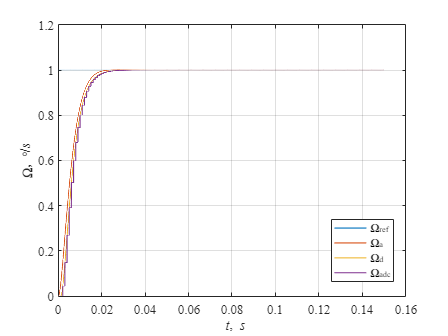

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);
wadc = b.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
plot(t,wadc,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d','\Omega_{adc}', 'location', 'best')

*Рисунок 18 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором, цифровой системы *

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t1: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t1: 6.2*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 6.2*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 0.0%


To =2Tt

Tt=0.001;
To=2*Tt;
spl.Tz=1.5*To;
spl.Tu=Tt+spl.Tz;
spl.Kpa = ob.J/kdw/3/ob.Ce/spl.Tu;
spl.Kpd = spl.Kpa;

Tmdl=0.05;
warning off
b = sim('SUAP_4_lb2','ReturnWorkspaceOutputs', 'on') ;

Found algebraic loop containing: 
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
SUAP_4_lb2/Ob/DC Motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
SUAP_4_lb2/Ob/DC Motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
SUAP_4_lb2/Ob/Current Reg/Sum1
SUAP_4_lb2/Ob/Current Reg/Gain
SUAP_4_lb2/Ob/Current Reg/Sum (algebraic variable)
Found algebraic loop cont

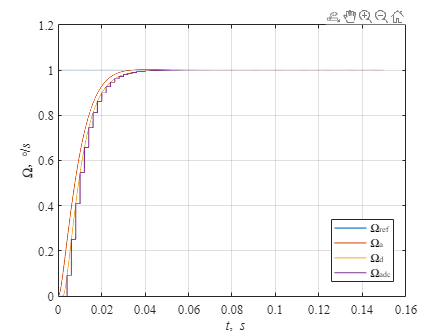

warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);
wadc = b.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
plot(t,wadc,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm, \circ/\its')
legend ('\Omega_{ref}', '\Omega_a','\Omega_d','\Omega_{adc}', 'location', 'best')

*Рисунок 19 – График заданной скорости, скорости с аналоговым п-регулятором, с дискретным п-регулятором, цифровой системы *

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 6.1*Tu


D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса t2: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса t2: 6.1*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 0.0%


**Вывод: **в ходе работы была произведена настройка системы на оптимум по модулю и биномиальный оптимум. 

Аналитически было найдено значение , при котором процессы в исследуемой цифровой системе и эквивалентной модели максимально приближены друг к другу:  $T_z=0.5T_0$.